clear
clc
% Empty folder to remove previous elements that have different size
mkdir('images')

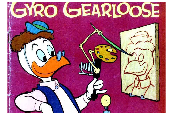

if exist('images', 'dir')
    rmdir('images', 's');  
end


% Get reference image
[file, path] = uigetfile('ref_images/*.png;*.jpg', 'Choose reference image');
ref_img = imread(append(path,file));
[rows, cols, channels] = size(ref_img);

% Downsample image to reduce kmeans computation time
color_resize = double(input("Downscale image for faster color clustering? Enter 1 if no. "));
if color_resize ~= 1
    lab_ref_img = rgb2lab(imresize(ref_img, color_resize, 'nearest'), "ColorSpace","srgb","WhitePoint","d65");
else
    lab_ref_img = rgb2lab(ref_img, "ColorSpace","srgb","WhitePoint","d65");
end

% Upscale image to fit more blocks
upscale = double(input("Upscale image to fit more blocks Enter 1 if no. "));
if upscale ~= 1
    ref_img = imresize(ref_img, upscale, 'nearest');
end

% Promt for block size
block_size = double(input('Size of 1x1 block? '));

% Promt number of colors
n_clusters = int16(input('How many colors do you want? '));
random = input("1 = random. 2 = k-means. ");
if random == 2
    [~, lab_cluster] = imsegkmeans(im2single(lab_ref_img),n_clusters);

    for i=1:n_clusters
        color_hex{i} = rgb2hex(lab2rgb(lab_cluster(i,:)));
    end
else
    color_hex = random_hex_colors(n_clusters);
end



% Create an element for each color in range [0, 1] as double
rgb_1x1_blocks = create_1x1_block(color_hex', block_size);
rgb_2x1_blocks = create_2x1_block(rgb_1x1_blocks, color_hex', block_size);
rgb_1x2_blocks = create_1x2_block(rgb_1x1_blocks, color_hex', block_size);
rgb_2x2_blocks = create_2x2_block(rgb_1x2_blocks, color_hex', block_size);
rgb_4x2_blocks = create_4x2_block(rgb_2x2_blocks, color_hex', block_size);
rgb_2x4_blocks = create_2x4_block(rgb_2x2_blocks, color_hex', block_size);

% Store elements as png images in 'images'-folder
export_elements_as_PNG(rgb_1x1_blocks, '1x1');
export_elements_as_PNG(rgb_2x1_blocks, '2x1');
export_elements_as_PNG(rgb_1x2_blocks, '1x2');
export_elements_as_PNG(rgb_2x2_blocks, '2x2');
export_elements_as_PNG(rgb_4x2_blocks, '4x2');
export_elements_as_PNG(rgb_2x4_blocks, '2x4');

% Get cell array of png images in range [0, 1] as double
images_1x1 = retrieve_images('images/1x1');
images_1x2 = retrieve_images('images/1x2');
images_2x1 = retrieve_images('images/2x1');
images_2x2 = retrieve_images('images/2x2');
images_2x4 = retrieve_images('images/2x4');
images_4x2 = retrieve_images('images/4x2');
block_images = [images_1x1; images_1x2; images_2x1; images_2x2; images_2x4; images_4x2];

% Compute CIELAB for each 1x1 image (assume larger blocks have same values)
for i=1:size(images_1x1,2)
    cielab_colors{i} = rgb2lab(mean_color(images_1x1{i}),'ColorSpace','srgb','WhitePoint','d65');
end

% Read image to reconstruct
imshow(ref_img);

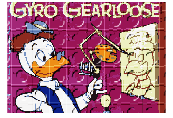


[final_image, cp] = legonization(block_images, ref_img, block_size, cielab_colors);

imshow(final_image);

if ~exist('cool_results', 'dir')
    mkdir('cool_results/');
end
out_folder=dir('cool_results/*.png');
number=size(out_folder,1)+1;

% Normal lego image
disp('Normal lego');disp('');

Normal lego


snr=compute_snr(im2double(ref_img), final_image)

snr = 5.4880

[d_mean, d_max] = compute_deltaE(rgb2lab(ref_img,"ColorSpace","srgb","WhitePoint","d65"), rgb2lab(final_image, 'ColorSpace','srgb','WhitePoint','d65'))

d_mean = 17.5034

d_max = 117.2849


out_name = append('cool_results/',num2str(number),'_normal_',num2str(length(color_hex)),'_',num2str(block_size), '_', num2str(snr), '.png');
imwrite(final_image, out_name);

% Apply brightness to blocks based on pixel by pixel L-values in original
disp('Pixel-by-pixel brightness lego');disp('');

Pixel-by-pixel brightness lego


final_image = apply_brightness(ref_img, final_image, 0.5);
snr=compute_snr(im2double(ref_img), final_image)

snr = 5.2127

[d_mean, d_max] = compute_deltaE(rgb2lab(ref_img,"ColorSpace","srgb","WhitePoint","d65"), rgb2lab(final_image, 'ColorSpace','srgb','WhitePoint','d65'))

d_mean = 18.5804

d_max = 118.0994

out_name = append('cool_results/',num2str(number),'_brightpixel_',num2str(length(color_hex)),'_',num2str(block_size), '_', num2str(snr), '.png');
imwrite(final_image, out_name);

% Apply brightness based on mean L-value in original image
disp('Mean brightness lego');disp('');

Mean brightness lego


final_image = apply_brightness_mean(ref_img, final_image, 0.5);
snr=compute_snr(im2double(ref_img), final_image)

snr = 4.9642

[d_mean, d_max] = compute_deltaE(rgb2lab(ref_img,"ColorSpace","srgb","WhitePoint","d65"), rgb2lab(final_image, 'ColorSpace','srgb','WhitePoint','d65'))

d_mean = 19.3941

d_max = 118.1957

out_name = append('cool_results/',num2str(number),'_brightmean_',num2str(length(color_hex)),'_',num2str(block_size), '_', num2str(snr), '.png');
imwrite(final_image, out_name);

% Apply block brightness to blocks based on mean L-value in original
disp('Block brightness lego');disp('');

Block brightness lego


final_image = apply_block_brightness(ref_img, final_image, 0.5, block_size);
snr=compute_snr(im2double(ref_img), final_image)

snr = 4.7731

[d_mean, d_max] = compute_deltaE(rgb2lab(ref_img,"ColorSpace","srgb","WhitePoint","d65"), rgb2lab(final_image, 'ColorSpace','srgb','WhitePoint','d65'))

d_mean = 20.3829

d_max = 118.2085

out_name = append('cool_results/',num2str(number),'_brightblock_',num2str(length(color_hex)),'_',num2str(block_size), '_', num2str(snr), '.png');
imwrite(final_image, out_name);
% Använd slumpmässiga färger och k-means och jämför mått för 3 olika bilder